# Introduction to Predator Prey Models

## Sec 1: Classic Predator-Prey (Lotka-Volterra)

Suppose there is a population of rabbits and foxes. The rabbits eat unlimited grass while the foxes can only eat the rabbits. How can we describe how the rabbit population, $R$, chages over time? What about the fox population, $F$? How do they interact with each other?

We can write the following equations:


$$dR/dt = \alpha R - \beta RF$$



$$dF/dt = \delta RF - \gamma F$$


with the following parameters:

$\alpha$ = growth rate of rabbits

$\beta$ = death rate of rabbits

$\delta$ = growth rate of foxes

$\gamma$ = death rate of foxes

These equations describe how the populations change over time. We can solve them using $ode45$ to visualize what happens to the populations.

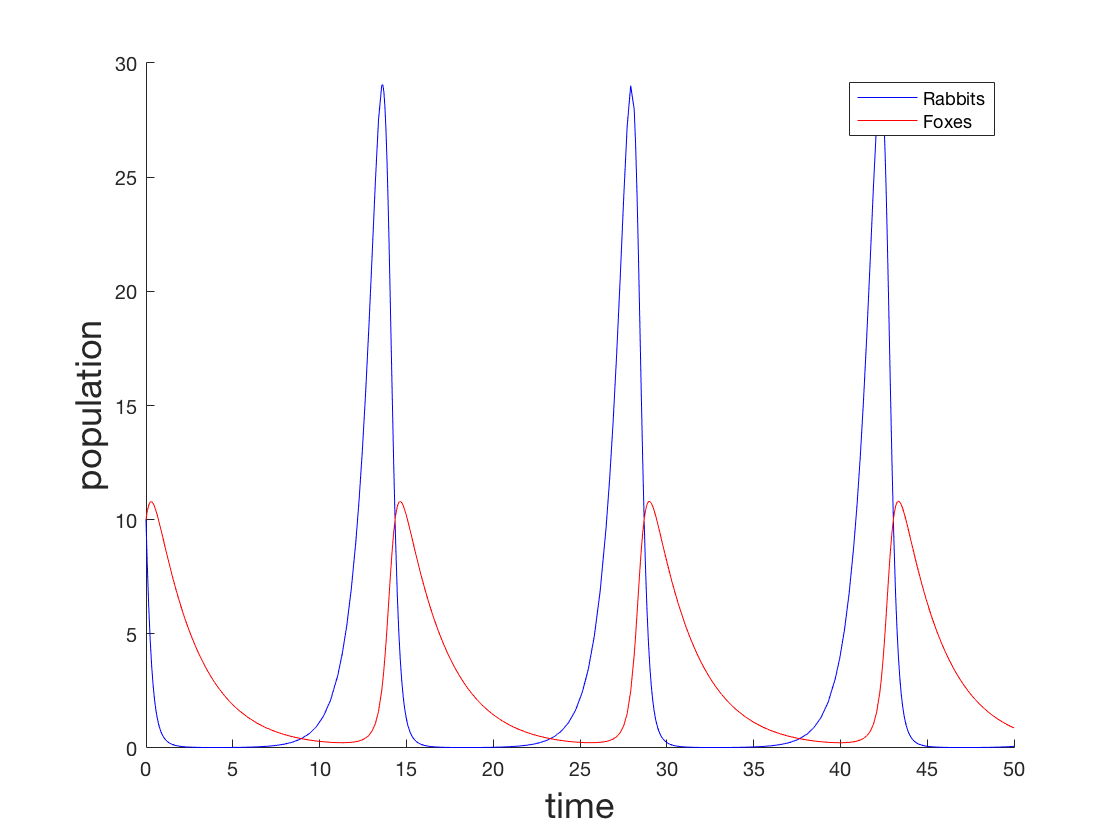

% set parameters (birth, death rates)
alpha = 6;
beta = 0.2;
delta = 0.1;
gamma = 1;

% set initial population sizes
R0 = 10;
F0 = 10;

% write system of odes
dRFdt = @(RF) [alpha*RF(1) - beta*RF(1)*RF(2);...
               delta*RF(1)*RF(2) - gamma*RF(2)];

% solve
[t,RF] = ode45(@(t,x) dRFdt(x),[0 50],[R0;F0]);

% plot
figure; clf; hold on;
plot(t,RF(:,1),'b');
plot(t,RF(:,2),'r');
xlabel('time','FontSize',18);
ylabel('population','FontSize',18);
legend('Rabbits','Foxes');

## Sec 2. Rosenzweig-MacArthur model

The Lotke-Volterra model of predator-prey dynamics uses some assumptions which may or may not be reasonable, depending on the system being studied.

For rabbits, it seems unlikely that there is either infinite food or infinite space to sustain an unlimited population. For the foxes, it's unlikely that their stomachs can perpetually eat rabbits without getting full.

It's fairly straightforward to modify the original model to account for new limitations such as these.

These particular limitations are introduced in the Rosenzweig-MacArthur extension of predator-prey:


$$dR/dt = R\left(1-\frac{R}{K}\right) - q \cdot F\left(\frac{R}{M+R}\right)$$



$$dF/dt = p F\left(\frac{R}{M+R}\right) - c F$$


We can set up and solve these equations. What's different about these equations? What's different about the steady state?

One of the changes brought to this model is the carrrying capacity, $K$. What happens when you increase $K$? Does this make sense?

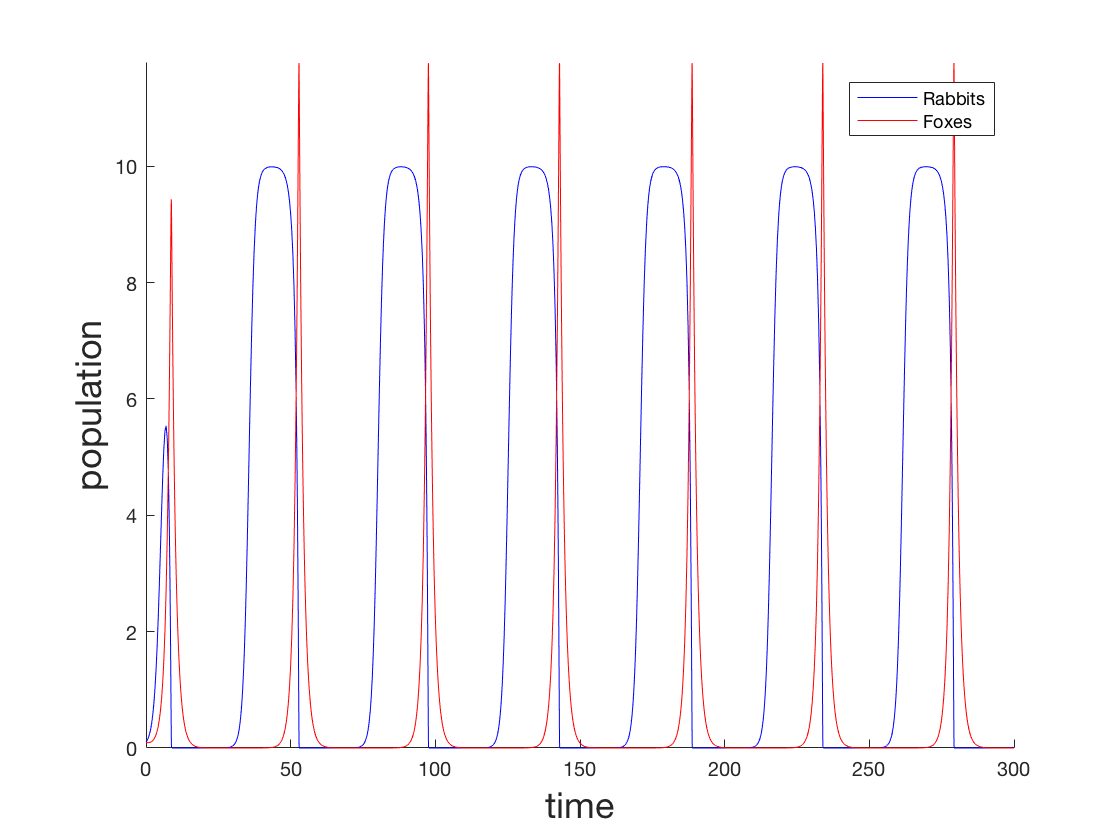

% set parameters (birth, death rates, carrying capacity etc)
K = 10; %0.4
p = 1.5;
q = 1;
c = 0.7;
M = 0.2;

% set initial population sizes
R0 = 0.1;
F0 = 0.1;

% write system of odes
dRFdt = @(RF) [RF(1)*(1-RF(1)/K) - q*RF(2)*(RF(1)/(M+RF(1)));...
               p*RF(2)*(RF(1)/(M+RF(1))) - c*RF(2)];


% solve
[t,RF] = ode45(@(t,x) dRFdt(x),[0 300],[R0;F0]);

% plot
figure; clf; hold on;
plot(t,RF(:,1),'b');
plot(t,RF(:,2),'r');
ylim([0 Inf]); % giving Inf or -Inf for a bound allows auto-set for single bound
xlabel('time','FontSize',18);
ylabel('population','FontSize',18);
legend('Rabbits','Foxes');

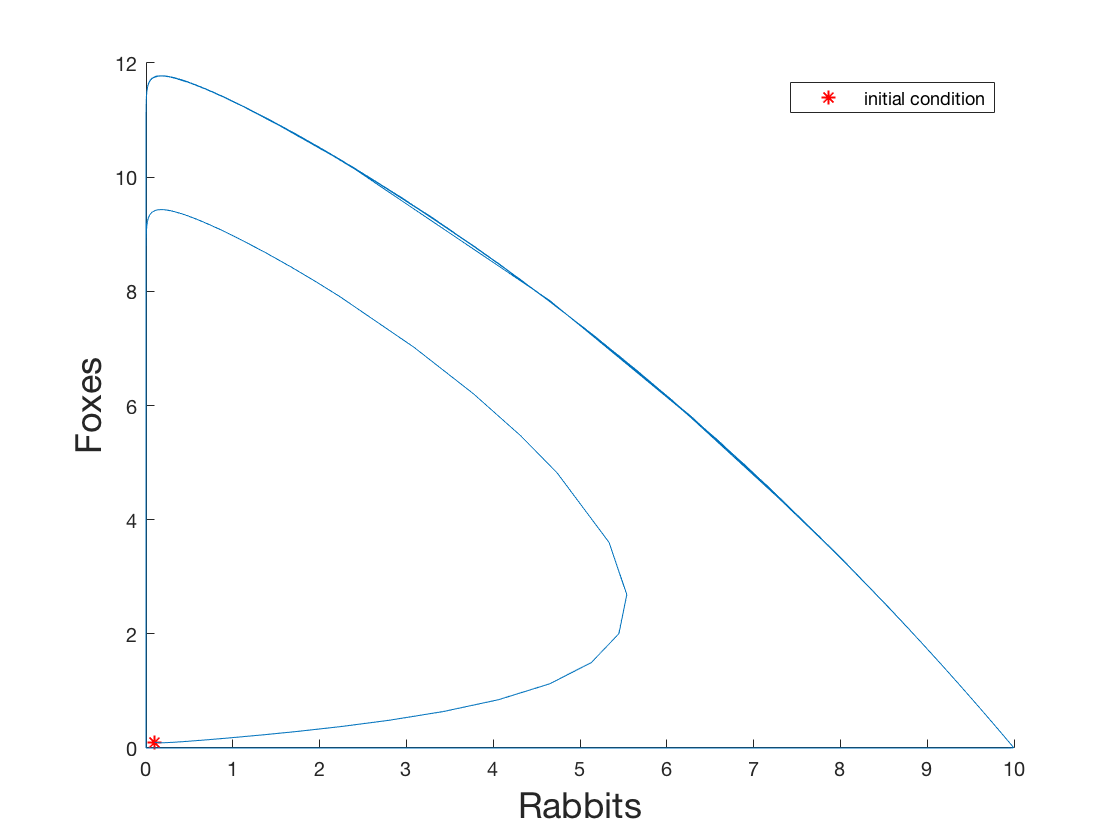

% plot trajectory of rabbit and fox populations over time
figure; clf; hold on;
plot(RF(1,1),RF(1,2),'*r'); 
plot(RF(:,1),RF(:,2),'-');
xlabel('Rabbits','FontSize',18);
ylabel('Foxes','FontSize',18);
legend('initial condition')